# CPM analysis

**By**: 김덕우

**Date** : 230411 

**Copyright** : 

*BE-sig* : *B*uilding *E*nergy *sig*nature Toolkit Copyright (c) 2023 Korea Institute of Civil Engineering and Building Technology, KICT (subject to receipt of any required approvals from South Korea Ministry of Land, Infrastructure and Transport, MOLIT). All rights reserved.

If you have questions about your rights to use or distribute this code, please contact KICT at [deukwookim@kict.re.kr](mailto:deukwookim@kict.re.kr).

NOTICE. This source code was developed under funding from the MOLIT South Korea Government consequently retains certain rights. As such, the South Korea Government has been granted for itself and others acting on its behalf a paid-up, nonexclusive, irrevocable, worldwide license in the code to reproduce, distribute copies to the public, prepare derivative works, and perform publicly and display publicly, and to permit other to do so.

clc
clearvars
% close all


## 환경설정

% 1. 입출력 파일 경로 
pathnm_csv='.\data input\csv_CPM\';
pathnm_pics='.\data input\pics_CPM\';

[checkF] = fnExistFolder( pathnm_csv );
[checkF] = fnExistFolder( pathnm_pics );

% 2. 기상 데이터 경로
weather_path = '.\data input\weather and holidays\';

% 3. 기상대 위치 설정
loc =108;

% example 1 
% path_data = ['.\data input\Y_monthly.csv'];
% path_data = ['.\data input\Y_daily.csv'];
% bld_str = 'test'; 



% Below two examples are intended to show the performance difference between original and MultiStarting search algorithms
% See the shape differences in model type 5p.

% example 2 
path_data = ['.\data input\Y_monthly_41220-52882.csv'];
bld_str = '41220-52882'; 

% example 3 (newly added)
% path_data = ['.\data input\Y_monthly_41670-100177112.csv'];
% bld_str = '41670-100177112'; 




## Y 에너지 데이터 읽기


Y = readtable(path_data,'Format', '%s%s%f');

% Duration 
if numel(Y.USE_DATE{1}) == 6
    [y, ~, ~] = ymd(datetime(Y.USE_DATE,"InputFormat",'yyyyMM'));
elseif numel(Y.USE_DATE{1}) == 8
    [y, ~, ~] = ymd(datetime(Y.USE_DATE,"InputFormat",'yyyyMMdd'));
else 
    msg = 'ERROR : Check size of "Y.USE_DATE" '
    assert(false, msg)
end



date_start = min ( unique(y) );
date_end   = max ( unique(y) );
% date_end   = 2019;
yrs_vec    = date_start : date_end;


## X 기상데이터 읽기

% 경로 : Do not modify

% Region : Do not modify
fnm = [weather_path,'최적기상대목록 210217.xlsx'];
T_station = readtable(fnm);
T_wea = [];


for m = 1:numel(yrs_vec)
    
    if numel(Y.USE_DATE{1}) == 6
        fnm  = [weather_path,'T_weather_all_monthly_',num2str(yrs_vec(m)),'.csv'];
    elseif numel(Y.USE_DATE{1}) == 8
        fnm  = [weather_path,'T_weather_all_daily_',num2str(yrs_vec(m)),'.csv'];
    end

    opts = detectImportOptions(fnm);
    opts.SelectedVariableNames = {'loc','t_avg','USE_YM'};
    opts = setvartype(opts,{'t_avg'},'double');
    opts = setvartype(opts,{'USE_YM'},'char');
    T_wea0 = readtable(fnm,opts);
    T_wea = [T_wea ; T_wea0];
end
T_wea.Properties.VariableNames{'USE_YM'} = 'USE_DATE';
X = T_wea(T_wea.loc == loc,["USE_DATE","t_avg"]);


## Dataset

dataset = innerjoin(Y,X);
Tout    = (dataset.t_avg)';
Y_ini   = (dataset.EUSE)';


## 그룹화 변수 

 [date_index] = fn_CPM_date_index(Y);



## Fill missing

if numel(Y.USE_DATE{1}) == 6
    Y_ini(isnan(Y_ini)) = 0;
elseif numel(Y.USE_DATE{1}) == 8
    [Y_ini,TF] = fillmissing(Y_ini,'spline');
    Y_ini(isnan(Y_ini)) = 0;
else
end 


## CPM run

% [save_T_stat, C_cookd, C_ZRE] = fn_CPM_run(Tout, Y_ini, pathnm_csv, pathnm_pics, bld_str, date_start, date_end);
[save_T_stat, C_cookd, C_ZRE] = fn_CPM_run_MS(Tout, Y_ini, pathnm_csv, pathnm_pics, bld_str, date_start, date_end);

MultiStart가 모든 시작점에서 실행을 완료했습니다. 

20번의 로컬 솔버 실행이 모두 수렴되었고 양수 로컬 솔버 exitflag가 반환되었습니다.

MultiStart가 모든 시작점에서 실행을 완료했습니다. 

20번의 로컬 솔버 실행이 모두 수렴되었고 양수 로컬 솔버 exitflag가 반환되었습니다.

MultiStart가 모든 시작점에서 실행을 완료했습니다. 

20번의 로컬 솔버 실행이 모두 수렴되었고 양수 로컬 솔버 exitflag가 반환되었습니다.

MultiStart가 모든 시작점에서 실행을 완료했습니다. 

20번의 로컬 솔버 실행이 모두 수렴되었고 양수 로컬 솔버 exitflag가 반환되었습니다.

MultiStart가 모든 시작점에서 실행을 완료했습니다. 

20번의 로컬 솔버 실행이 모두 수렴되었고 양수 로컬 솔버 exitflag가 반환되었습니다.

MultiStart가 모든 시작점에서 실행을 완료했습니다. 

20번의 로컬 솔버 실행이 모두 수렴되었고 양수 로컬 솔버 exitflag가 반환되었습니다.


save_T_stat.Es = repmat({'총계'},size(save_T_stat,1),1);
CPM_type_best = save_T_stat.CPM_TY;


## save CPM results


root_path = '.\data input\';
csv_name = ['CPM_Result_pk',bld_str];
writetable(save_T_stat, [pathnm_csv,csv_name, num2str(date_start), num2str(date_end)],"Delimiter","\t",'Encoding','UTF-8')


## CPM plot

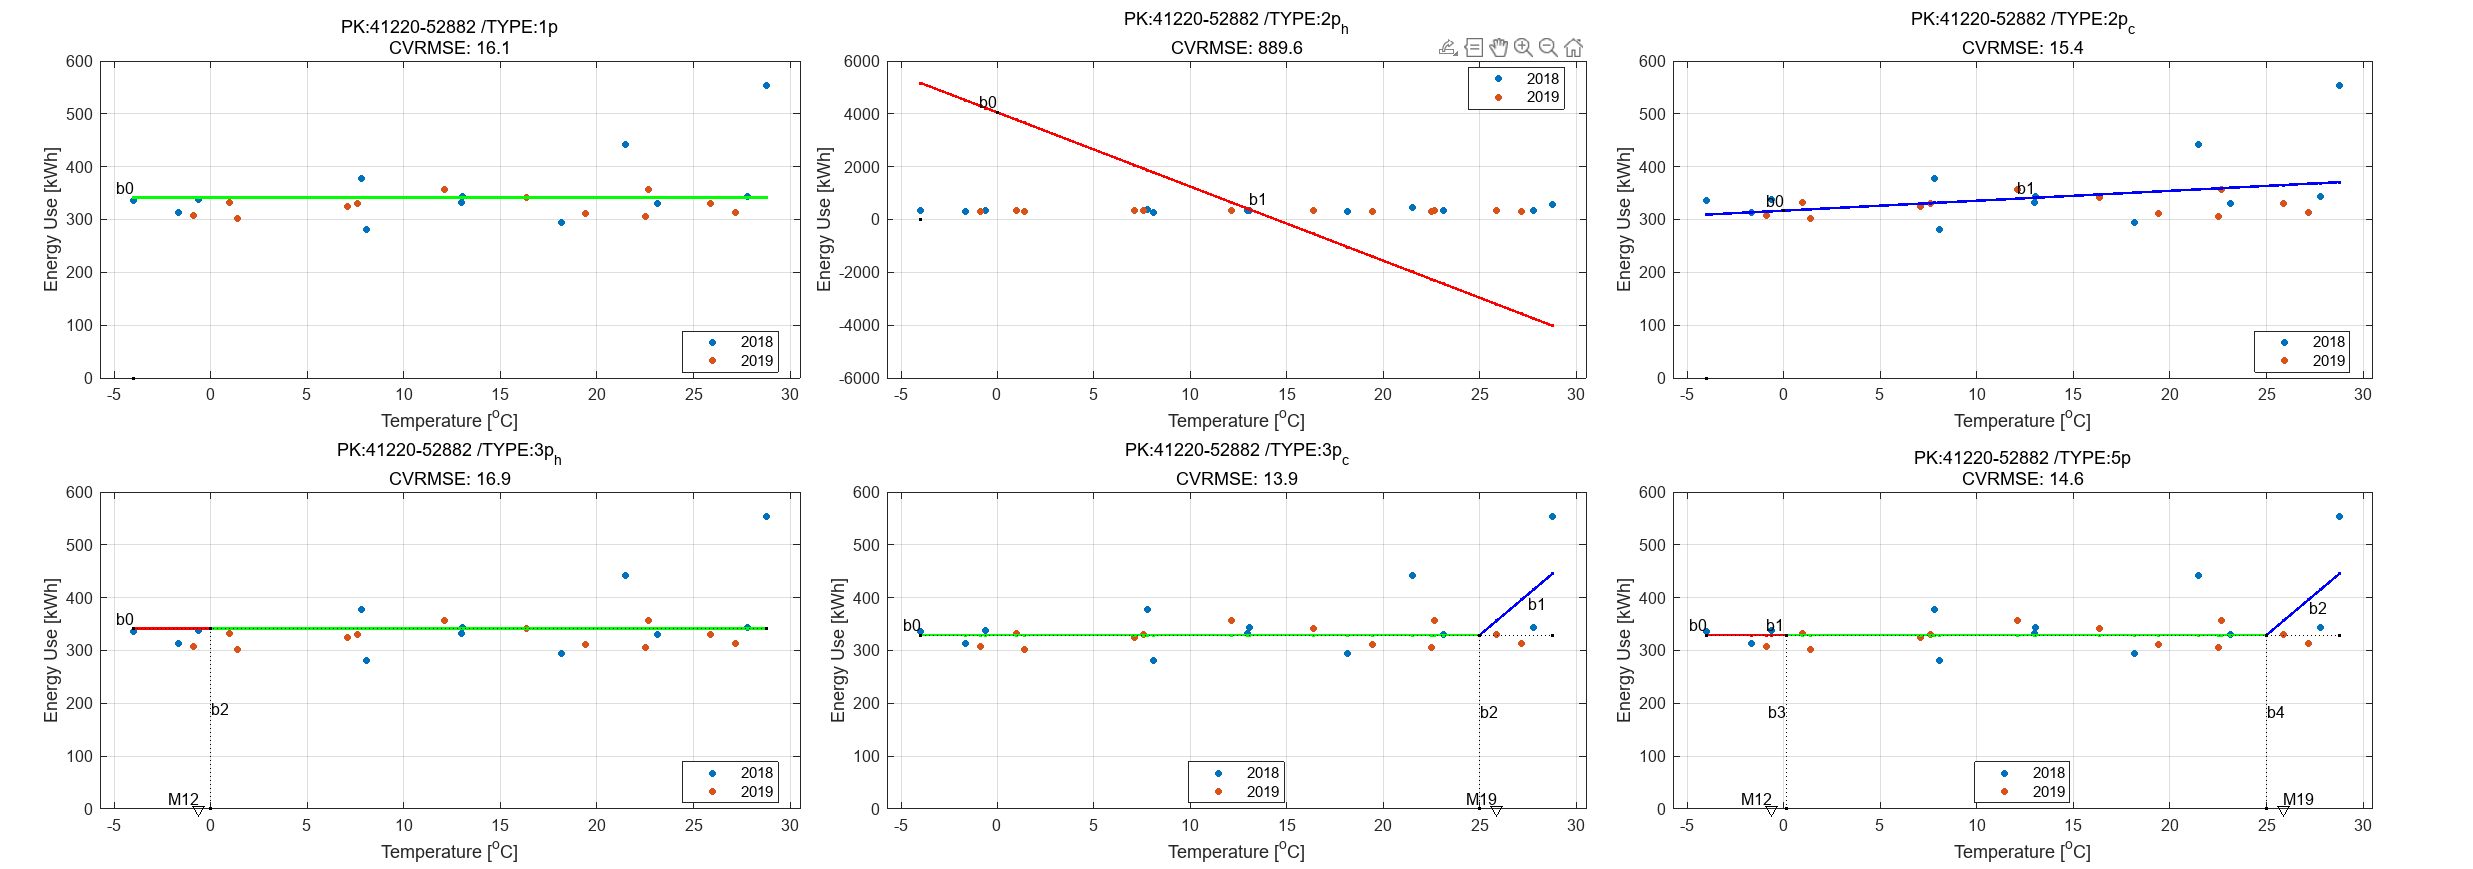

figure('units','normalized','outerPosition',[0.1 0.1 0.8 0.7])
t=tiledlayout(2,3, 'TileSpacing','compact', 'Padding', 'compact');

for k=1:6
    nexttile
    fn_CPM_plot_bestfit(1 , save_T_stat(k,:), C_cookd(k,:), C_ZRE(k,:), Tout, Y_ini, pathnm_csv, pathnm_pics, bld_str, date_start, date_end, CPM_type_best(k,:), date_index);
end

pic_name = ['CPM_bestfit0_Tot_pk',bld_str];
saveas(gcf, [pathnm_pics, pic_name, num2str(date_start), num2str(date_end)], 'png')